# Multilabel Text Classification Using Deep Learning

This example shows how to classify text data that has multiple independent labels.

For classification tasks where there can be multiple independent labels for each observation—for example, tags on an scientific article—you can train a deep learning model to predict probabilities for each independent class. To enable a network to learn multilabel classification targets, you can optimize the loss of each class independently using binary cross-entropy loss.

This example defines a deep learning model that classifies subject areas given the abstracts of mathematical papers collected using the arXiv API [1]. The model consists of a word embedding and GRU, max pooling operation, fully connected, and sigmoid operations.

To measure the performance of multilabel classification, you can use the labeling F-score [2]. The labeling F-score evaluates multilabel classification by focusing on per-text classification with partial matches. The measure is the normalized proportion of matching labels against the total number of true and predicted labels.

This example defines the following model:

- A word embedding that maps a sequence of words to a sequence of numeric vectors.

- A GRU operation that learns dependencies between the embedding vectors.

- A max pooling operation that reduces a sequence of feature vectors to a single feature vector.

- A fully connected layer that maps the features to the binary outputs.

- A sigmoid operation for learning the binary cross entropy loss between the outputs and the target labels.

This diagram shows a piece of text propagating through the model architecture and outputting a vector of probabilities. The probabilities are independent, so they need not sum to one.

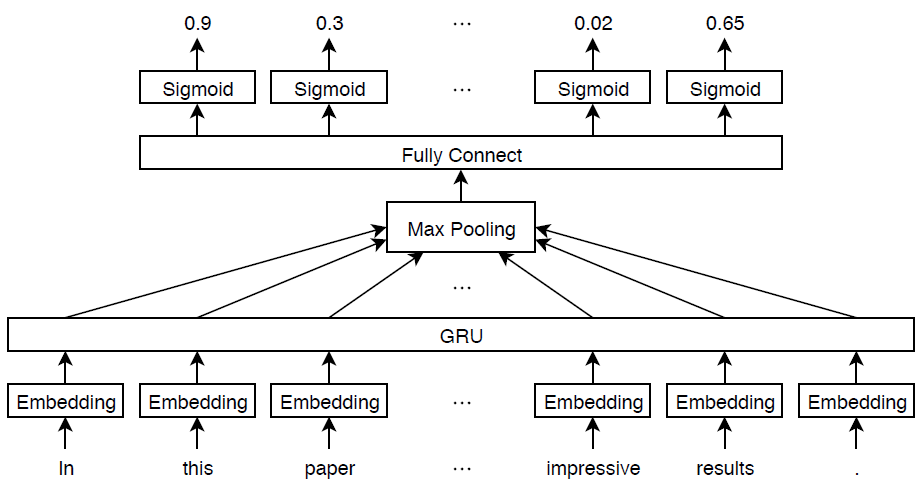

## Import Text Data

Import a set of abstracts and category labels from computer science papers using the arXiv API. Specify the number of records to import using the `importSize` variable. Note that the arXiv API is rate limited to querying 1000 articles at a time and requires waiting between requests.

importSize = 50000;

Import the first set of records.

url = "https://export.arxiv.org/oai2?verb=ListRecords" + ...
    "&set=cs" + ...
    "&metadataPrefix=arXiv";
options = weboptions('Timeout',160);
code = webread(url,options);

Parse the returned XML content and create an array of `htmlTree` objects containing the record information.

tree = htmlTree(code);
subtrees = findElement(tree,"record");
numel(subtrees)

ans = 1000

Iteratively import more chunks of records until the required amount is reached, or there are no more records. To continue importing records from where you left off, use the `resumptionToken` attribute from the previous result. To adhere to the rate limits imposed by the arXiv API, add a delay of 20 seconds before each query using the `pause` function.

while numel(subtrees) < importSize
    subtreeResumption = findElement(tree,"resumptionToken");
    
    if isempty(subtreeResumption)
        break
    end
    
    resumptionToken = extractHTMLText(subtreeResumption);
    
    url = "https://export.arxiv.org/oai2?verb=ListRecords" + ...
        "&resumptionToken=" + resumptionToken;
    
    pause(20)
    code = webread(url,options);
    
    tree = htmlTree(code);
    
    subtrees = [subtrees; findElement(tree,"record")];
end

## Extract and Preprocess Text Data

Extract the abstracts and labels from the parsed HTML trees.

Find the `"<abstract>"` and `"<categories>"` elements using the `findElement` function.

subtreeAbstract = htmlTree("");
subtreeCategory = htmlTree("");

for i = 1:numel(subtrees)
    subtreeAbstract(i) = findElement(subtrees(i),"abstract");
    subtreeCategory(i) = findElement(subtrees(i),"categories");
end

Extract the text data from the subtrees containing the abstracts using the `extractHTMLText` function.

textData = extractHTMLText(subtreeAbstract);

Tokenize and preprocess the text data using the `preprocessText` function, listed at the end of the example.

documentsAll = preprocessText(textData);
documentsAll(1:5)

ans =   1×5 tokenizedDocument:

     72 tokens: describe new algorithm $(k,\ell)$ pebble game color obtain characterization family $(k,\ell)$ sparse graph algorithmic solution family problem concern tree decomposition graph special instance sparse graph appear rigidity theory receive increase attention recent year particular colored pebble generalize strengthen previous result lee streinu give new proof tuttenashwilliams characterization arboricity present new decomposition certify sparsity base $(k,\ell)$ pebble game color work expose connection pebble game algorithm previous sparse graph algorithm gabow gabow westermann hendrickson
     44 tokens: quantum mechanical model diosi feldmann kosloff arrive conjecture state limit entropy certain mixture relative entropy system size infinity conjecture prove paper density matrix first proof analytic quantum law large number second clarifies relation channel capacity p

Extract the labels from the subtrees containing the labels.

strLabels = extractHTMLText(subtreeCategory);
labelsAll = arrayfun(@split,strLabels,'UniformOutput',false);

Remove labels that do not belong to the `"cs"` set.

for i = 1:numel(labelsAll)
    labelsAll{i} = labelsAll{i}(startsWith(labelsAll{i},"cs."));
end

Visualize some of the classes in a word cloud. Find the documents corresponding to the following:

- Abstracts tagged with "Artificial Intelligence" and not tagged with `"Computer Vision"`

- Abstracts tagged with "`Computer Vision`" and not tagged with `"`Artificial Intelligence`"`

- Abstracts tagged with both `"`Artificial Intelligence`"` and `"Computer Vision"`

Find the document indices for each of the groups using the `ismember` function.

idxAI = cellfun(@(lbls) ismember("cs.AI",lbls) && ~ismember("cs.CV",lbls),labelsAll);
idxCV = cellfun(@(lbls) ismember("cs.CV",lbls) && ~ismember("cs.AI",lbls),labelsAll);
idxAICV = cellfun(@(lbls) ismember("cs.AI",lbls) && ismember("cs.CV",lbls),labelsAll);

Visualize the documents for each group in a word cloud.

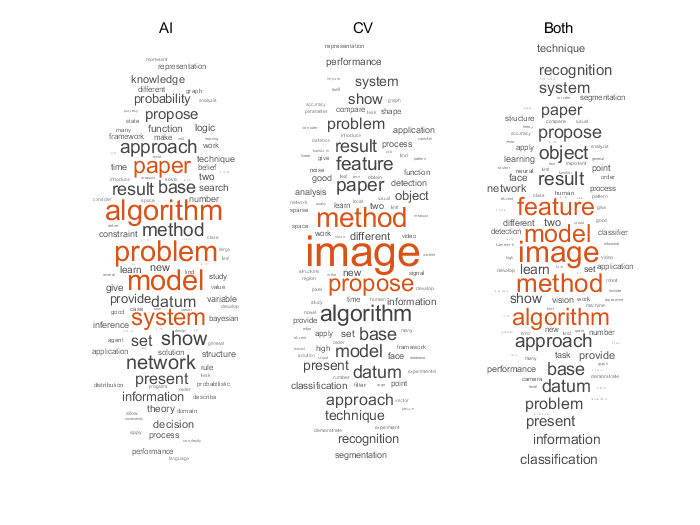

figure
subplot(1,3,1)
wordcloud(documentsAll(idxAI));
title("AI")

subplot(1,3,2)
wordcloud(documentsAll(idxCV));
title("CV")

subplot(1,3,3)
wordcloud(documentsAll(idxAICV));
title("Both")

View the number of classes.

classNames = unique(cat(1,labelsAll{:}));
numClasses = numel(classNames)

numClasses = 40

Visualize the number of per-document labels using a histogram.

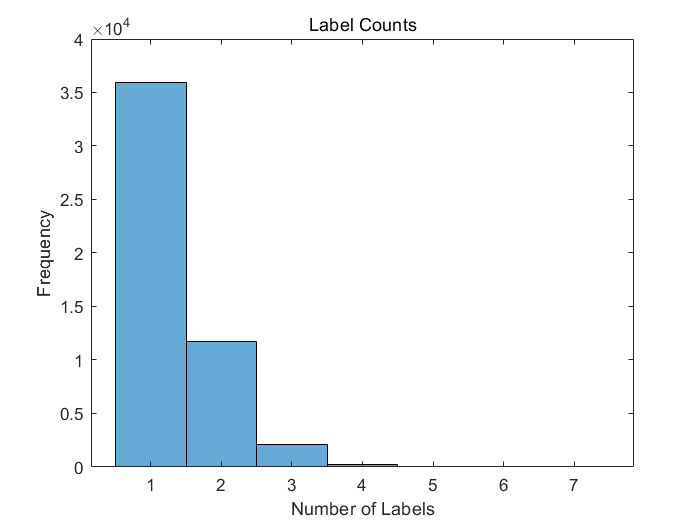

labelCounts = cellfun(@numel, labelsAll);
figure
histogram(labelCounts)
xlabel("Number of Labels")
ylabel("Frequency")
title("Label Counts")

## Prepare Text Data for Deep Learning

Partition the data into training and validation partitions using the `cvpartition` function. Hold out 10% of the data for validation by setting the `'HoldOut'` option to 0.1.

cvp = cvpartition(numel(documentsAll),'HoldOut',0.1);
documentsTrain = documentsAll(training(cvp));
documentsValidation = documentsAll(test(cvp));

labelsTrain = labelsAll(training(cvp));
labelsValidation = labelsAll(test(cvp));

Create a word encoding object that encodes the training documents as sequences of word indices. Specify a vocabulary of the 5000 words by setting the `'Order'` option to `'frequency'`, and the `'MaxNumWords'` option to 5000.

enc = wordEncoding(documentsTrain,'Order','frequency','MaxNumWords',5000)

enc =   wordEncoding - 属性:

      NumWords: 5000
    Vocabulary: [1×5000 string]


To improve training, use the following techniques:

- When training, truncate the documents to a length that reduces the amount of padding used and does not does discard too much data.

- Train for one epoch with the documents sorted by length in ascending order, then shuffle the data each epoch. This technique is known as *sortagrad*.

To choose a sequence length for truncation, visualize the document lengths in a histogram and choose a value that captures most of the data.

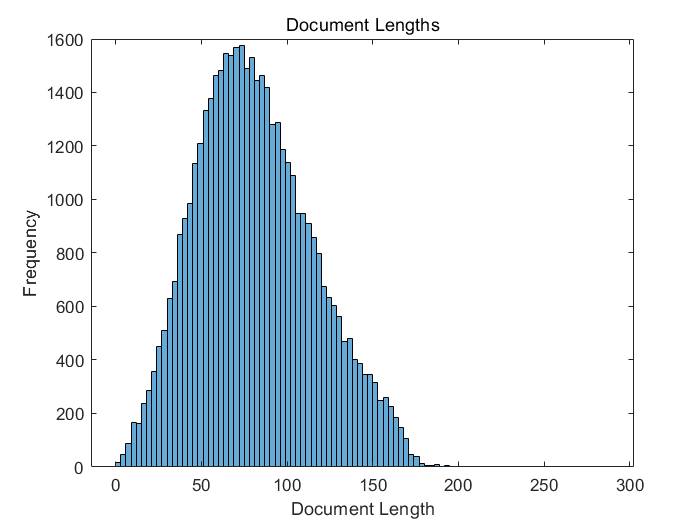

documentLengths = doclength(documentsTrain);

figure
histogram(documentLengths)
xlabel("Document Length")
ylabel("Frequency")
title("Document Lengths")

Most of the training documents have fewer than 175 tokens. Use 175 tokens as the target length for truncation and padding.

maxSequenceLength = 175;

To use the sortagrad technique, sort the documents by length in ascending order.

[~,idx] = sort(documentLengths);
documentsTrain = documentsTrain(idx);
labelsTrain = labelsTrain(idx);

## Define and Initialize Model Parameters

Define the parameters for each of the operations and include them in a struct. Use the format `parameters.OperationName.ParameterName`, where `parameters` is the struct, O`perationName` is the name of the operation (for example `"fc"`), and `ParameterName` is the name of the parameter (for example, `"Weights"`).

Create a struct `parameters` containing the model parameters. Initialize the bias with zeros. Use the following weight initializers for the operations:

- For the embedding, initialize the weights with random normal values.

- For the GRU operation, initialize the weights using the `initializeGlorot` function, listed at the end of the example.

- For the fully connect operation, initialize the weights using the `initializeGaussian` function, listed at the end of the example.

embeddingDimension = 300;
numHiddenUnits = 250;
inputSize = enc.NumWords + 1;

parameters = struct;
parameters.emb.Weights = dlarray(randn([embeddingDimension inputSize]));

parameters.gru.InputWeights = dlarray(initializeGlorot(3*numHiddenUnits,embeddingDimension));
parameters.gru.RecurrentWeights = dlarray(initializeGlorot(3*numHiddenUnits,numHiddenUnits));
parameters.gru.Bias = dlarray(zeros(3*numHiddenUnits,1,'single'));

parameters.fc.Weights = dlarray(initializeGaussian([numClasses,numHiddenUnits]));
parameters.fc.Bias = dlarray(zeros(numClasses,1,'single'));

View the `parameters` struct.

parameters

parameters = 包含以下字段的 struct :
    emb: [1×1 struct]
    gru: [1×1 struct]
     fc: [1×1 struct]


View the parameters for the GRU operation.

parameters.gru

ans = 包含以下字段的 struct :
        InputWeights: [750×300 dlarray]
    RecurrentWeights: [750×250 dlarray]
                Bias: [750×1 dlarray]


### Define Model Function

Create the function `model`, listed at the end of the example, which computes the outputs of the deep learning model described earlier. The function `model` takes as input the input data `dlX` and the model parameters `parameters`. The network outputs the predictions for the labels.

### Define Model Gradients Function

Create the function `modelGradients`, listed at the end of the example, which takes as input a mini-batch of input data `dlX` and the corresponding targets `T` containing the labels, and returns the gradients of the loss with respect to the learnable parameters, the corresponding loss, and the network outputs.

## Specify Training Options

Train for 5 epochs with a mini-batch size of 256.

numEpochs = 5;
miniBatchSize = 256;

Train using the Adam optimizer, with a learning rate of 0.01, and specify gradient decay and squared gradient decay factors of 0.5 and 0.999, respectively.

learnRate = 0.01;
gradientDecayFactor = 0.5;
squaredGradientDecayFactor = 0.999;

Clip the gradients with a threshold of 1 using $L_2$ norm gradient clipping.

gradientThreshold = 1;

Visualize the training progress in a plot.

plots = "training-progress";

To convert a vector of probabilities to labels, use the labels with probabilities higher than a specified threshold. Specify a label threshold of 0.5.

labelThreshold = 0.5;

Validate the network every epoch.

numObservationsTrain = numel(documentsTrain);
numIterationsPerEpoch = floor(numObservationsTrain/miniBatchSize);
validationFrequency = numIterationsPerEpoch;

Train on a GPU if one is available. This requires Parallel Computing Toolbox™. Using a GPU requires Parallel Computing Toolbox™ and a CUDA® enabled NVIDIA® GPU with compute capability 3.0 or higher.

executionEnvironment = "auto";

## Train Model

Train the model using a custom training loop.

For each epoch, loop over mini-batches of data. At the end of each epoch, shuffle the data. At the end of each iteration, update the training progress plot.

For each mini-batch:

- Convert the documents to sequences of word indices and convert the labels to dummy variables.

- Convert the sequences to `dlarray` objects with underlying type single and specify the dimension labels `'BCT'` (batch, channel, time).

- For GPU training, convert to `gpuArray` objects.

- Evaluate the model gradients and loss using `dlfeval` and the `modelGradients` function.

- Clip the gradients.

- Update the network parameters using the `adamupdate` function.

- If necessary, validate the network using the `modelPredictions` function, listed at the end of the example.

- Update the training plot.

Initialize the training progress plot.

if plots == "training-progress"
    figure
    
    % Labeling F-Score.
    subplot(2,1,1)
    lineFScoreTrain = animatedline('Color',[0 0.447 0.741]);
    lineFScoreValidation = animatedline( ...
        'LineStyle','--', ...
        'Marker','o', ...
        'MarkerFaceColor','black');
    ylim([0 1])
    xlabel("Iteration")
    ylabel("Labeling F-Score")
    grid on
    
    % Loss.
    subplot(2,1,2)
    lineLossTrain = animatedline('Color',[0.85 0.325 0.098]);
    lineLossValidation = animatedline( ...
        'LineStyle','--', ...
        'Marker','o', ...
        'MarkerFaceColor','black');
    ylim([0 inf])
    xlabel("Iteration")
    ylabel("Loss")
    grid on
end

Initialize parameters for the Adam optimizer.

trailingAvg = [];
trailingAvgSq = [];

Prepare the validation data. Create a one-hot encoded matrix where non-zero entries correspond to the labels of each observation.

numObservationsValidation = numel(documentsValidation);
TValidation = zeros(numClasses, numObservationsValidation, 'single');
for i = 1:numObservationsValidation
    [~,idx] = ismember(labelsValidation{i},classNames);
    TValidation(idx,i) = 1;
end

Train the model.

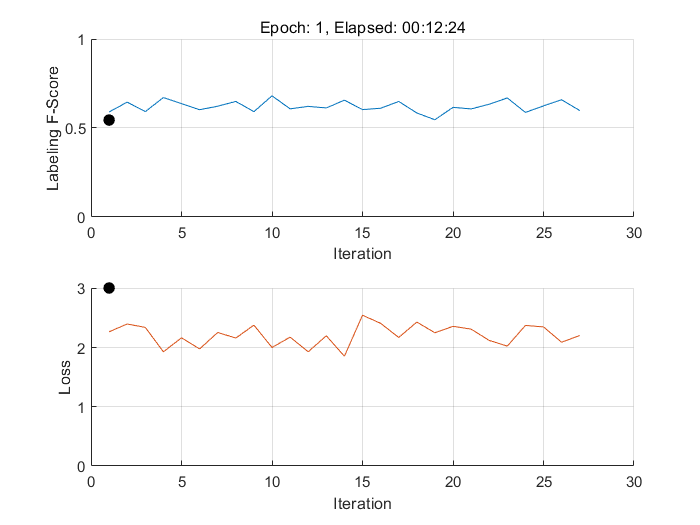

iteration = 0;
start = tic;

% Loop over epochs.
for epoch = 1:numEpochs
    
    % Loop over mini-batches.
    for i = 1:numIterationsPerEpoch
        iteration = iteration + 1;
        idx = (i-1)*miniBatchSize+1:i*miniBatchSize;
        
        % Read mini-batch of data and convert the labels to dummy
        % variables.
        documents = documentsTrain(idx);
        labels = labelsTrain(idx);
        
        % Convert documents to sequences.
        len = min(maxSequenceLength,max(doclength(documents)));
        X = doc2sequence(enc,documents, ...
            'PaddingValue',inputSize, ...
            'Length',len);
        X = cat(1,X{:});
        
        % Dummify labels.
        T = zeros(numClasses, miniBatchSize, 'single');
        for j = 1:miniBatchSize
            [~,idx2] = ismember(labels{j},classNames);
            T(idx2,j) = 1;
        end
        
        % Convert mini-batch of data to dlarray.
        dlX = dlarray(X,'BTC');
        
        % If training on a GPU, then convert data to gpuArray.
        %if (executionEnvironment == "auto" && canUseGPU) || executionEnvironment == "gpu"
        dlX = gpuArray(dlX);
        %end
        
        % Evaluate the model gradients, state, and loss using dlfeval and the
        % modelGradients function.
        [gradients,loss,dlYPred] = dlfeval(@modelGradients, dlX, T, parameters);
        
        % Gradient clipping.
        gradients = dlupdate(@(g) thresholdL2Norm(g, gradientThreshold),gradients);
        
        % Update the network parameters using the Adam optimizer.
        [parameters,trailingAvg,trailingAvgSq] = adamupdate(parameters,gradients, ...
            trailingAvg,trailingAvgSq,iteration,learnRate,gradientDecayFactor,squaredGradientDecayFactor);
        
        % Display the training progress.
        if plots == "training-progress"
            subplot(2,1,1)
            D = duration(0,0,toc(start),'Format','hh:mm:ss');
            title("Epoch: " + epoch + ", Elapsed: " + string(D))
            
            % Loss.
            addpoints(lineLossTrain,iteration,double(gather(extractdata(loss))))
            
            % Labeling F-score.
            YPred = extractdata(dlYPred) > labelThreshold;
            score = labelingFScore(YPred,T);
            addpoints(lineFScoreTrain,iteration,double(gather(score)))
            
            drawnow
            
            % Display validation metrics.
            if iteration == 1 || mod(iteration,validationFrequency) == 0
                dlYPredValidation = modelPredictions(parameters,enc,documentsValidation,miniBatchSize,maxSequenceLength);
                
                % Loss.
                lossValidation = crossentropy(dlYPredValidation,TValidation, ...
                    'TargetCategories','independent', ...
                    'DataFormat','CB');
                addpoints(lineLossValidation,iteration,double(gather(extractdata(lossValidation))))
                
                % Labeling F-score.
                YPredValidation = extractdata(dlYPredValidation) > labelThreshold;
                score = labelingFScore(YPredValidation,TValidation);
                addpoints(lineFScoreValidation,iteration,double(gather(score)))
                
                drawnow
            end
        end
    end
    
    % Shuffle data.
    idx = randperm(numObservationsTrain);
    documentsTrain = documentsTrain(idx);
    labelsTrain = labelsTrain(idx);
end

## Test Model

To make predictions on a new set of data, use the `modelPredictions` function, listed at the end of the example. The `modelPredictions` function takes as input the model parameters, a word encoding, and an array of tokenized documents, and outputs the model predictions corresponding to the specified mini-batch size and the maximum sequence length.

dlYPredValidation = modelPredictions(parameters,enc,documentsValidation,miniBatchSize,maxSequenceLength);

To convert the network outputs to an array of labels, find the labels with scores higher than the specified label threshold.

YPredValidation = extractdata(dlYPredValidation) > labelThreshold;

To evaluate the performance, calculate the labeling F-score using the `labelingFScore` function, listed at the end of the example. The labeling F-score evaluates multilabel classification by focusing on per-text classification with partial matches.

score = labelingFScore(YPredValidation,TValidation)

score = single
0.5406

View the effect of the labeling threshold on the labeling F-score by trying a range of values for the threshold and comparing the results.

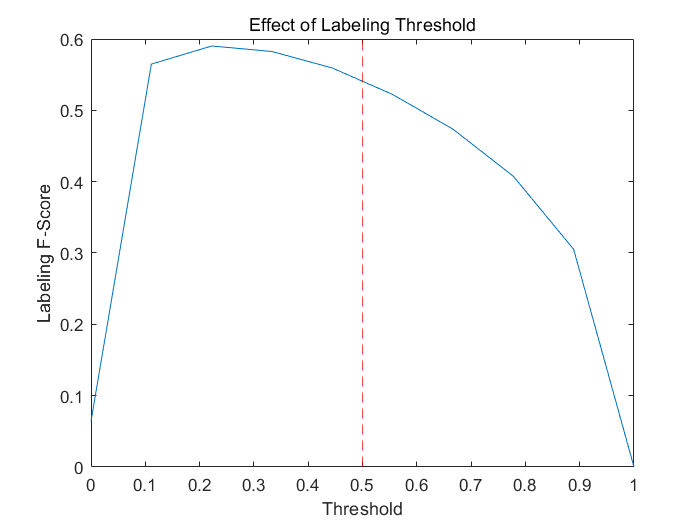

thr = linspace(0,1,10);
score = zeros(size(thr));
for i = 1:numel(thr)
    YPredValidationThr = extractdata(dlYPredValidation) >= thr(i);
    score(i) = labelingFScore(YPredValidationThr,TValidation);
end

figure
plot(thr,score)
xline(labelThreshold,'r--');
xlabel("Threshold")
ylabel("Labeling F-Score")
title("Effect of Labeling Threshold")

## Visualize Predictions

To visualize the correct predictions of the classifier, calculate the numbers of true positives. A true positive is an instance of a classifier correctly predicting a particular class for an observation.

Y = YPredValidation;
T = TValidation;

numTruePositives = sum(T & Y,2);

numObservationsPerClass = sum(T,2);
truePositiveRates = numTruePositives ./ numObservationsPerClass;

Visualize the numbers of true positives for each class in a histogram. 

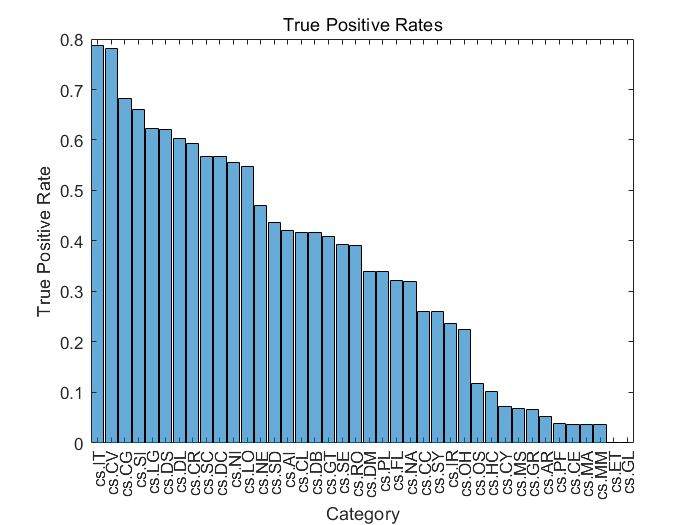

figure
[~,idx] = sort(truePositiveRates,'descend');
histogram('Categories',classNames(idx),'BinCounts',truePositiveRates(idx))
xlabel("Category")
ylabel("True Positive Rate")
title("True Positive Rates")

Visualize the instances where the classifier predicts incorrectly by showing the distribution of true positives, false positives, and false negatives. A false positive is an instance of a classifier assigning a particular incorrect class to an observation. A false negative is an instance of a classifier failing to assign a particular correct class to an observation.

Create a confusion matrix showing the true positive, false positive, and false negative counts:

- For each class, display the true positive counts on the diagonal.

- For each pair of classes (*i*,*j*), display the number of instances of a false positive for *j* when the instance is also a false negative for *i*.

That is, the confusion matrix with elements given by:

    
$$\text{TPFN}_{ij} = 
\begin{cases}
\text{numTruePositives}(i), & \text{if } i = j \\
{\text{numFalsePositives}(j | i\text{ is a false negative})}, & \text{if } i \ne j
\end{cases}$$


Calculate the false negatives and false positives.

falseNegatives = T & ~Y;
falsePositives = ~T & Y;

Calculate the off-diagonal elements.

falseNegatives = permute(falseNegatives,[3 2 1]);
numConditionalFalsePositives = sum(falseNegatives & falsePositives, 2);
numConditionalFalsePositives = squeeze(numConditionalFalsePositives);

tpfnMatrix = numConditionalFalsePositives;

Set the diagonal elements to the true positive counts.

idxDiagonal = 1:numClasses+1:numClasses^2;
tpfnMatrix(idxDiagonal) = numTruePositives;

Visualize the true positive and false positive counts in a confusion matrix using the `confusionchart` function and sort the matrix such that the elements on the diagonal are in descending order.

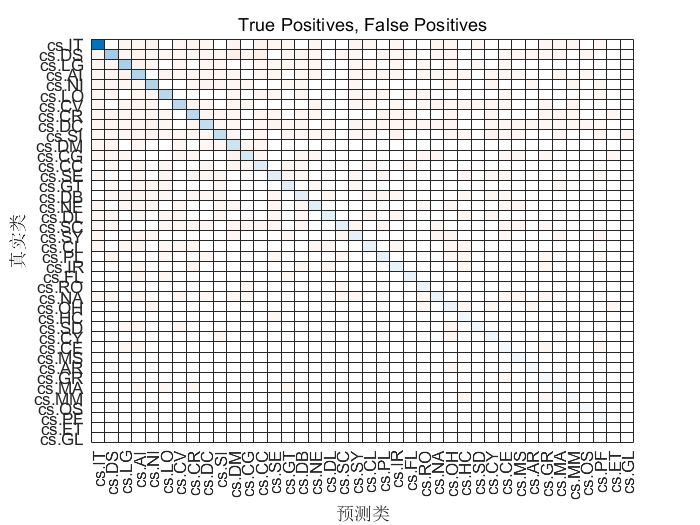

figure
cm = confusionchart(tpfnMatrix,classNames);
sortClasses(cm,"descending-diagonal");
title("True Positives, False Positives")

To view the matrix in more detail, open this example as a live script and open the figure in a new window.

## Preprocess Text Function

The `preprocessText` function tokenizes and preprocesses the input text data using the following steps:

- Tokenize the text using the `tokenizedDocument` function. Extract mathematical equations as a single token using the `'RegularExpressions'` option by specifying the regular expression `"\$.*?\$"`, which captures text appearing between two "$" symbols.

- Erase the punctuation using the `erasePunctuation` function.

- Convert the text to lowercase using the `lower` function.

- Remove the stop words using the `removeStopWords` function.

- Lemmatize the text using the `normalizeWords` function with the `'Style'` option set to `'lemma'`.

function documents = preprocessText(textData)

% Tokenize the text.
regularExpressions = table;
regularExpressions.Pattern = "\$.*?\$";
regularExpressions.Type = "equation";

documents = tokenizedDocument(textData,'RegularExpressions',regularExpressions);

% Erase punctuation.
documents = erasePunctuation(documents);

% Convert to lowercase.
documents = lower(documents);

% Lemmatize.
documents = addPartOfSpeechDetails(documents);
documents = normalizeWords(documents,'Style','Lemma');

% Remove stop words.
documents = removeStopWords(documents);

% Remove short words.
documents = removeShortWords(documents,2);

end

## Model Function

The function `model` takes as input the input data `dlX` and the model parameters `parameters`, and returns the predictions for the labels.

function dlY = model(dlX,parameters)

% Embedding
weights = parameters.emb.Weights;
dlX = embedding(dlX, weights);

% GRU
inputWeights = parameters.gru.InputWeights;
recurrentWeights = parameters.gru.RecurrentWeights;
bias = parameters.gru.Bias;

numHiddenUnits = size(inputWeights,1)/3;
hiddenState = dlarray(zeros([numHiddenUnits 1]));

dlY = gru(dlX, hiddenState, inputWeights, recurrentWeights, bias,'DataFormat','CBT');

% Max pooling along time dimension
dlY = max(dlY,[],3);

% Fully connect
weights = parameters.fc.Weights;
bias = parameters.fc.Bias;
dlY = fullyconnect(dlY,weights,bias,'DataFormat','CB');

% Sigmoid
dlY = sigmoid(dlY);

end

## Model Gradients Function

The `modelGradients` function takes as input a mini-batch of input data `dlX` with corresponding targets `T` containing the labels and returns the gradients of the loss with respect to the learnable parameters, the corresponding loss, and the network outputs.

function [gradients,loss,dlYPred] = modelGradients(dlX,T,parameters)

dlYPred = model(dlX,parameters);

loss = crossentropy(dlYPred,T,'TargetCategories','independent','DataFormat','CB');

gradients = dlgradient(loss,parameters);

end

## Model Predictions Function

The `modelPredictions` function takes as input the model parameters, a word encoding, an array of tokenized documents, a mini-batch size, and a maximum sequence length, and returns the model predictions by iterating over mini-batches of the specified size.

function dlYPred = modelPredictions(parameters,enc,documents,miniBatchSize,maxSequenceLength)

inputSize = enc.NumWords + 1;

numObservations = numel(documents);
numIterations = ceil(numObservations / miniBatchSize);

numFeatures = size(parameters.fc.Weights,1);
dlYPred = zeros(numFeatures,numObservations,'like',parameters.fc.Weights);

for i = 1:numIterations
    
    idx = (i-1)*miniBatchSize+1:min(i*miniBatchSize,numObservations);
    
    len = min(maxSequenceLength,max(doclength(documents(idx))));
    X = doc2sequence(enc,documents(idx), ...
        'PaddingValue',inputSize, ...
        'Length',len);
    X = cat(1,X{:});
    
    dlX = dlarray(X,'BTC');
    
    dlYPred(:,idx) = model(dlX,parameters);
end

end

## Labeling F-Score Function

The labeling F-score function [2] evaluates multilabel classification by focusing on per-text classification with partial matches. The measure is the normalized proportion of matching labels against the total number of true and predicted labels given by

    
$$\frac{1}{N}\sum_{n=1}^N \left( \frac{2\sum_{c=1}^CY_{nc}T_{nc}}{\sum_{c=1}^C (Y_{nc} + T_{nc})}\right),$$


where *N* and *C* correspond to the number of observations and classes, respectively, and *Y* and *T* correspond to the predictions and targets, respectively.

function score = labelingFScore(Y,T)

numObservations = size(T,2);

scores = (2 * sum(Y .* T)) ./ sum(Y + T);
score = sum(scores) / numObservations;

end

## Glorot Weights Initialization Function

The `initializeGlorot` function generates an array of weights according to Glorot initialization.

function weights = initializeGlorot(numOut, numIn)

varWeights = sqrt( 6 / (numIn + numOut) );
weights = varWeights * (2 * rand([numOut, numIn], 'single') - 1);

end

## Gaussian Weights Initialization Function

The `initializeGaussian` function samples weights from a Gaussian distribution with mean 0 and standard deviation 0.01.

function parameter = initializeGaussian(sz)

parameter = randn(sz,'single') .* 0.01;

end

## Embedding Function

The `embedding` function maps numeric indices to the corresponding vector given by the input weights.

function Z = embedding(X, weights)
% Reshape inputs into a vector.
[N, T] = size(X, 2:3);
X = reshape(X, N*T, 1);

% Index into embedding matrix.
Z = weights(:, X);

% Reshape outputs by separating batch and sequence dimensions.
Z = reshape(Z, [], N, T);
end

## $L_2$ Norm Gradient Clipping Function

The `thresholdL2Norm` function scales the input gradients so that their $L_2$ norm values equal the specified gradient threshold when the $L_2$ norm value of the gradient of a learnable parameter is larger than the specified threshold.

function gradients = thresholdL2Norm(gradients,gradientThreshold)

gradientNorm = sqrt(sum(gradients(:).^2));
if gradientNorm > gradientThreshold
    gradients = gradients * (gradientThreshold / gradientNorm);
end

end

## References

- arXiv. "arXiv API." Accessed January 15, 2020. [https://arxiv.org/help/api](https://arxiv.org/help/api) 

- Sokolova, Marina, and Guy Lapalme. "A Sytematic Analysis of Performance Measures for Classification Tasks." *Information Processing & Management* 45, no. 4 (2009): 427–437.

*Copyright 2019 The MathWorks, Inc.*